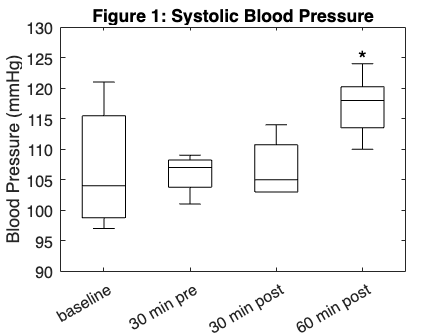

clear vars; close all; clc

% load data

sb_base = [117, 115, 121, 97, 99, 98, 104, 101, 105].';
sb_pre = [107, 107, 109, 108, 109, 107, 101, 103, 104].';
sb_30post = [105, 110, 103, 104, 114, 106, 103, 113, 103].';
sb_60post = [115, 118, 119, 119, 124, 124, 110, 112, 114].';
sb = zeros(9, 4);
sb(:,1) = sb_base;
sb(:,2) = sb_pre;
sb(:,3) = sb_30post;
sb(:,4) = sb_60post;

db_base = [74, 76, 78, 57, 59, 59, 70, 66, 72];
db_pre = [67, 67, 71, 65, 66, 66, 76, 70, 70];
db_30post = [61, 63, 68, 70, 67, 69, 74, 69, 66];
db_60post = [70, 82, 73, 74, 74, 73, 80, 76, 76];
db = zeros(9, 4);
db(:,1) = db_base;
db(:,2) = db_pre;
db(:,3) = db_30post;
db(:,4) = db_60post;

hr_base = [64, 61, 58, 60, 62, 61, 62, 64, 58];
hr_pre = [69, 64, 71, 58, 80, 62, 60, 63, 62];
hr_30post = [71, 68, 79, 83, 80, 80, 68, 74, 70];
hr_60post = [64, 61, 68, 76, 87, 82, 64, 70, 73];
hr = zeros(9, 4);
hr(:,1) = hr_base;
hr(:,2) = hr_pre;
hr(:,3) = hr_30post;
hr(:,4) = hr_60post;

% calculate mean, sd, confidence interval

% boxplot

labels = {'baseline', '30 min pre', '30 min post', '60 min post'};

figure (1)
boxplot(sb, 'Colors','k')
title ('Figure 1: Systolic Blood Pressure')
ylabel('Blood Pressure (mmHg)')
text(3.95, 125, '*', 'FontSize', 14)
ylim ([90 130])
set(gca,'xtick',[1:4],'xticklabel',labels)
h = findobj('LineStyle','--'); set(h, 'LineStyle','-');
saveas(gcf,'systolicbp', 'jpeg')

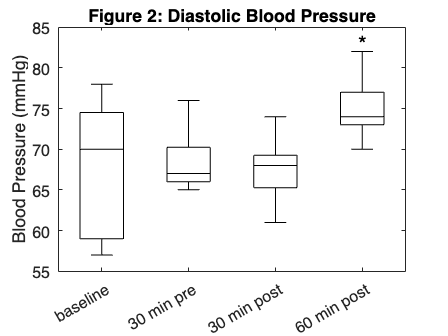



figure (2)
boxplot(db, 'Colors', 'k')
title ('Figure 2: Diastolic Blood Pressure')
ylabel('Blood Pressure (mmHg)')
text(3.95, 83, '*', 'FontSize', 14)
ylim ([55 85])
set(gca,'xtick',[1:4],'xticklabel',labels)
h = findobj('LineStyle','--'); set(h, 'LineStyle','-');
saveas(gcf,'diastolicbp', 'jpeg')

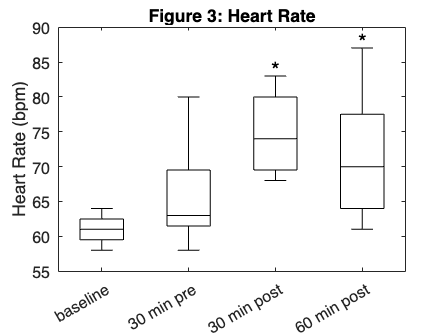


figure (3)
boxplot(hr, 'Colors', 'k')
title ('Figure 3: Heart Rate')
ylabel('Heart Rate (bpm)')
text(3.95, 88, '*', 'FontSize', 14)
text(2.95, 84, '*', 'FontSize', 14)
ylim ([55 90])
set(gca,'xtick',[1:4],'xticklabel',labels)
h = findobj('LineStyle','--'); set(h, 'LineStyle','-');
saveas(gcf,'heartrate', 'jpeg')